# Projeto 1 - 04/09

João Guilherme Martins Jatobá

18.01790-8

ECM303 - Sistemas de Controle

## **Pergunta 1**

Dados do enunciado (esperado)

% Começo
Mp = 0.163

Mp = 0.1630

zeta = sqrt((log(Mp)^2)/(pi^2+(log(Mp)^2)))

zeta = 0.5000

Ts_desejo = 3

Ts_desejo = 3

Wn_esperado = 3/(zeta*Ts_desejo)

Wn_esperado = 1.9998

%De acordo com a 2a forma canonica:
Kp_esperado = Wn_esperado^2

Kp_esperado = 3.9993

Gc_dado = tf(Kp_esperado,1)

Gc_dado =
 
  3.999
 
Static gain.



Gp = tf([1],[1 3 0])

Gp =
 
      1
  ---------
  s^2 + 3 s
 
Continuous-time transfer function.



Gma_dado = Gp*Gc_dado

Gma_dado =
 
    3.999
  ---------
  s^2 + 3 s
 
Continuous-time transfer function.



Sem usar dados do enunciado (Real)

%Sem usar os dados obtidos (Ts_desejo e Wn_esperado)
Gc_normal = @(Kp) (Kp)

Gc_normal = function_handle with value:
    @(Kp)(Kp)


%Gma_total = Gp*Gc_normal
Gma_total = @(Kp) (Kp/(s^2+3*s))

Gma_total = function_handle with value:
    @(Kp)(Kp/(s^2+3*s))


Gmf = @(Kp) (Kp/(s^2+3*s+Kp))

Gmf = function_handle with value:
    @(Kp)(Kp/(s^2+3*s+Kp))


%De acordo com a 2a forma canonica:
Wn_real = 3/(2*zeta)

Wn_real = 2.9997

Kp = Wn_real^2

Kp = 8.9985

Ts_real = 3/(zeta*Wn_real)

Ts_real = 2

## **Pergunta 2**

y0 = 1

y0 = 1

% Para y = y0, y' = 0 e y" = 0
u0 = sqrt(y0)

u0 = 1


$$G\left(s\right)=\frac{\Delta Y\left(s\right)}{\Delta U\left(s\right)}=\frac{1}{s^2 -s+0,5}$$


G = tf(1,[1 -1 0.5])

G =
 
        1
  -------------
  s^2 - s + 0.5
 
Continuous-time transfer function.



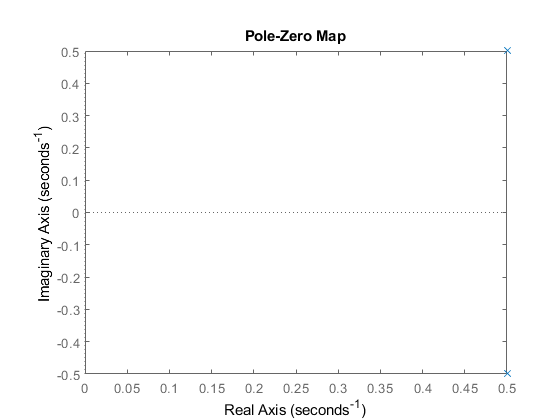

D = G.Denominator;
D = cell2mat(D);
raizes = roots(D);
figure(1)
pzmap(G);grid;